# Variables

clc
close all
clear

syms theta
syms phi

% Cinématique
l = 0.25; % 25cm
Wob = 240; % en RPM
Min = 0; %Minimum Graphique cinématique
Min2 = -pi/3; %Minimum Graphique Dynamique Statique
Max = pi/3;  %Maximum du graphique cinématique
g = 9.81;

% Statique dynamique
l0 = 0.5;    % 50 cm en M
m_A = 0.1;   % 100 g en Kg
m_BA = 1;    % 1 kg
A_BA = 5;    % 5 rad/sec




## Calculs Cinématique


Wob = (Wob * 2 * pi) / 60;   %Transfert vers Rad/s
l1 = l;      %l1 est égale a l
l2 = l;      %l2 est égale a l

theta1 = Wob;
theta2 = 0;

phi1 = Wob;
phi2 = A_BA;

%Position Horizontal
Ax = 2*l1*cos(theta);

%Position Vertical
%Ay = sqrt(((l1).^2) + ((l1*(sin(theta) - sqrt(1-((1-cos(theta)).^2)))).^2));
Ay = (l1*(sin(theta) - sqrt(1-((1-cos(theta)).^2))));

%Vitesse Horizontale
Vax = -2 * l1 * theta1 * sin(theta);

%Vitesse Vertical
Vay = l1*((theta1 * cos(theta)) + ((1-cos(theta))*sin(theta)*theta1)/sqrt(1-(1-cos(theta)).^2));

%Accélération Horizontal
Aax = -2 * (l1 * (theta1.^2) * cos(theta));

%Accélération Vertical
Aay = 0;

disp('Cinématique Horizontal')

Cinématique Horizontal


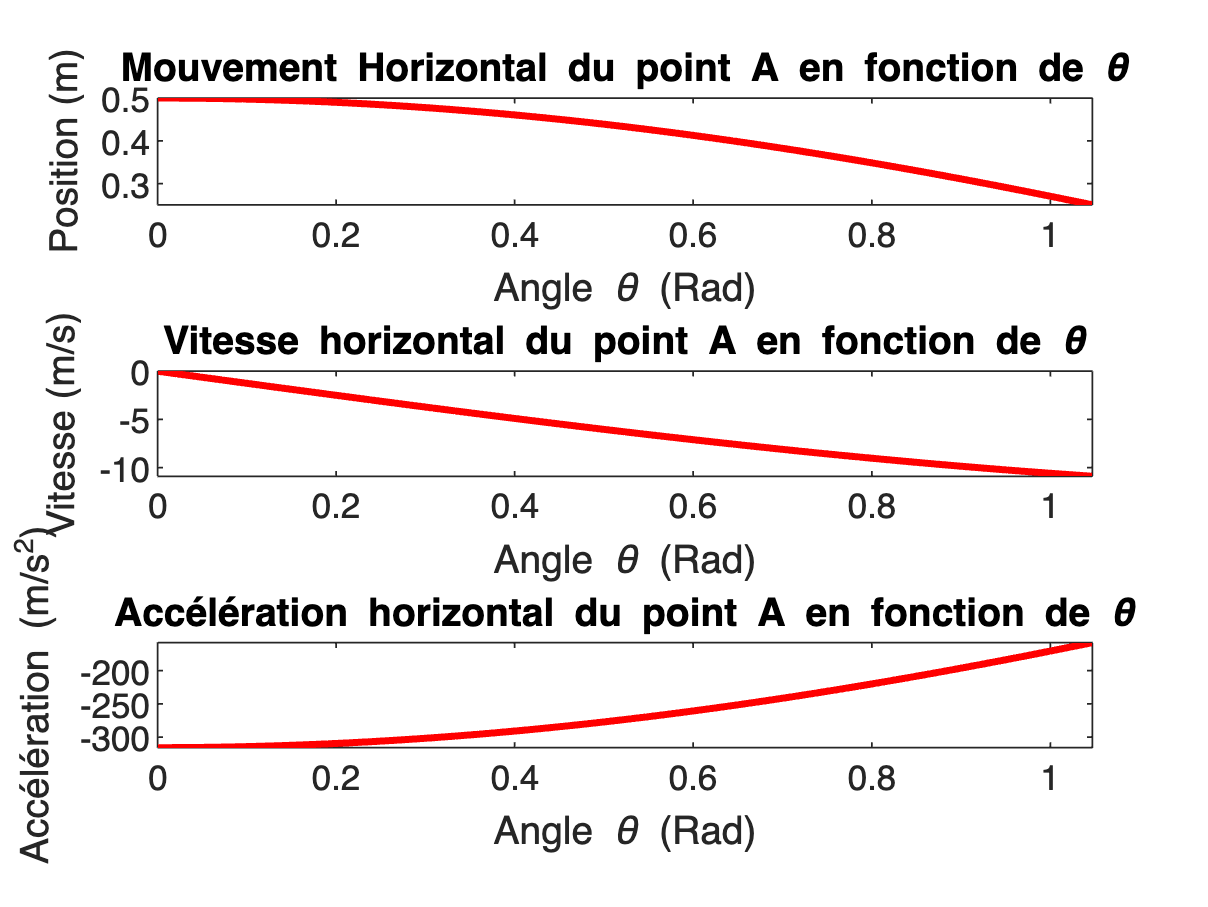


figure;
subplot(3, 1, 1)
fplot(Ax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Mouvement Horizontal du point A en fonction de \theta')
xlabel('Angle \theta (Rad)')
ylabel('Position (m)')
hold on
subplot(3, 1, 2)
fplot(Vax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Vitesse horizontal du point A en fonction de \theta')
xlabel('Angle \theta (Rad)')
ylabel('Vitesse (m/s)')
hold on
subplot(3, 1, 3)
fplot(Aax, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Accélération horizontal du point A en fonction de \theta')
xlabel('Angle \theta (Rad)')
ylabel('Accélération (m/s^2)')


disp('Cinématique Vertical')

Cinématique Vertical


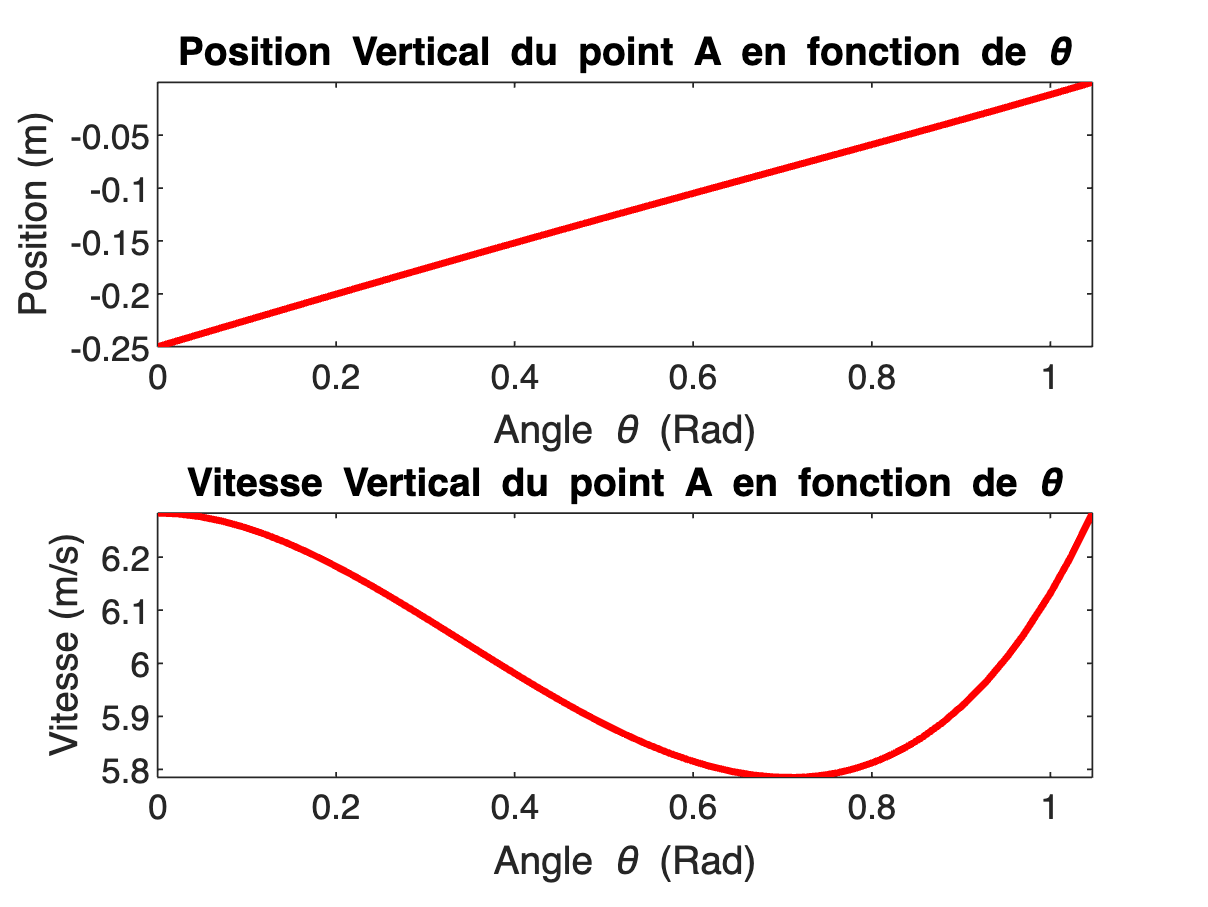


figure;
subplot(2, 1, 1)
fplot(Ay, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Position Vertical du point A en fonction de \theta')
xlabel('Angle \theta (Rad)')
ylabel('Position (m)')
hold on
subplot(2, 1, 2)
fplot(Vay, [Min Max], 'Color',"red", 'LineWidth', 2)
title('Vitesse Vertical du point A en fonction de \theta')
xlabel('Angle \theta (Rad)')
ylabel('Vitesse (m/s)')
hold on

## Calculs Statique et Dynamique


F_g = m_BA * g;
F_A = m_A * g;

%Couple statique
CB_stat = l2*cos(phi)*(((F_g)/2)+(F_A));

%Couple dynamique
CB_dyn = ((l2/2)*cos(phi)*F_g) + (l2*cos(phi)*F_A) + phi2 * ((((l2.^2)*m_BA)/3)+((l2.^2)*m_A));

disp('Statique et dynamique');

Statique et dynamique


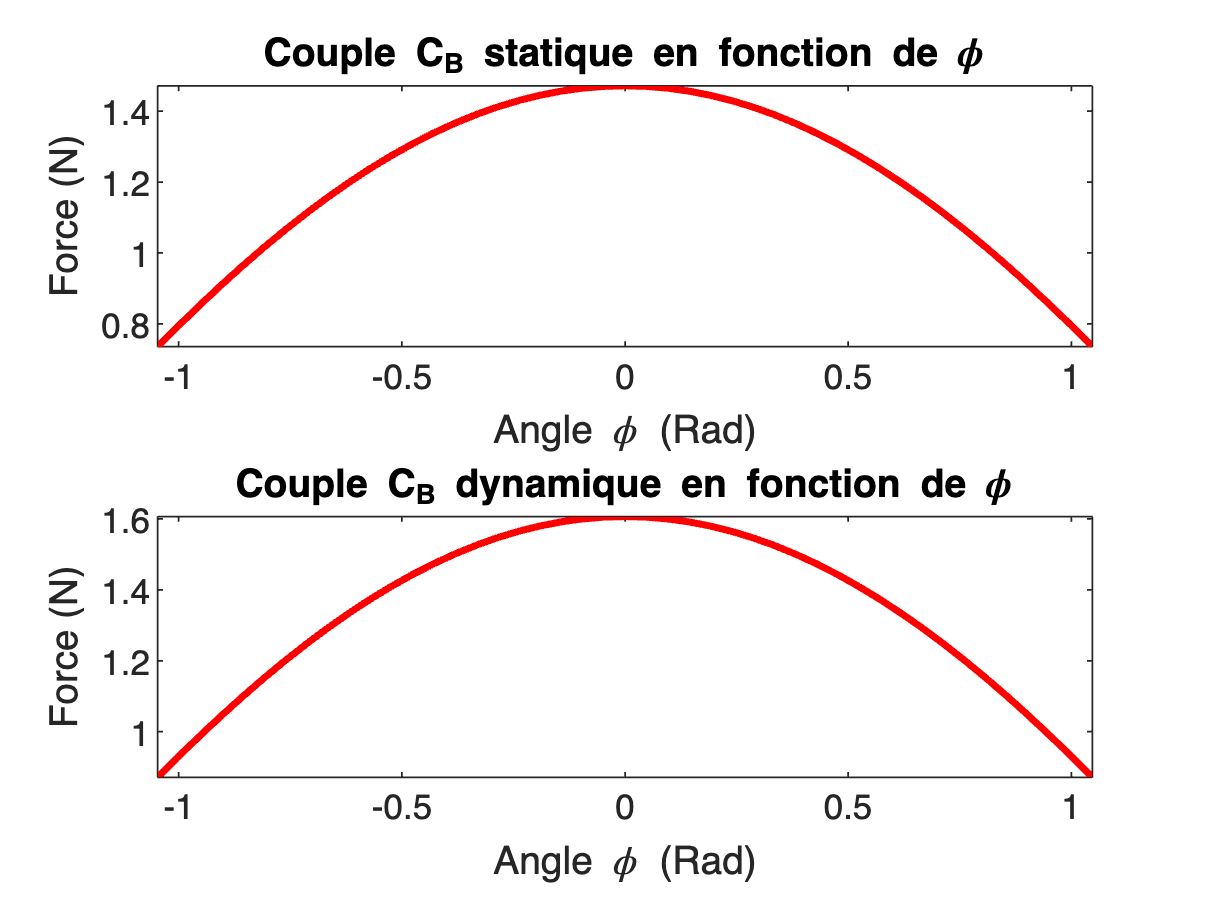


figure;
subplot(2, 1, 1);
fplot(CB_stat, [Min2 Max], 'Color',"red", 'LineWidth', 2);
title('Couple C_B statique en fonction de \phi');
xlabel('Angle \phi (Rad)');
ylabel('Force (N)');
hold on;

subplot(2, 1, 2)
fplot(CB_dyn, [Min2 Max], 'Color',"red", 'LineWidth', 2);
title('Couple C_B dynamique en fonction de \phi');
xlabel('Angle \phi (Rad)');
ylabel('Force (N)');
hold on;